Baa;

## 评估实现性能

codec_test2里面有循环 比较慢 最好用coder命令转成mex 会快十倍

errinp = logspace(-2-1/3,-1/3,10);%输入误码率从0.005到0.5
erroutp = zeros(1,10);
erroutp2 = zeros(1,10);
N=10;%每个信噪比运行这么多次仿真
NN=100000;%一次仿真处理这么多比特
w=waitbar(0);
for i=1:length(errinp)
    erroutp(i)=0;erroutp2(i)=0;
    for j=1:N
        erroutp(i) = erroutp(i) + codec_sys(errinp(i),5*7,NN);%一般回溯长度取约束长度的五倍
        erroutp2(i) = erroutp2(i) + codec_test2_mex(errinp(i),5*7,NN);
    end
    erroutp(i)=erroutp(i)/N;
    erroutp2(i)=erroutp2(i)/N;
    waitbar(i/N,w);
end
delete(w);
erroutp(erroutp==0) = 1/(N*NN);
erroutp2(erroutp2==0) = 1/(N*NN);

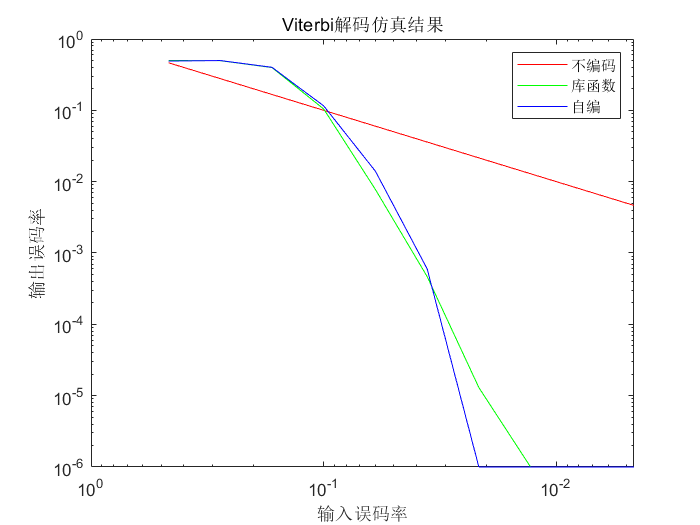

figure;
axes('XDir','reverse');
loglog(errinp,errinp,'r','DisplayName','不编码');hold on;
loglog(errinp,erroutp,'g','DisplayName','库函数');
loglog(errinp,erroutp2,'b','DisplayName','自编');
set(gca,'XDir','reverse')%对X方向反转
legend;
title("Viterbi解码仿真结果");
xlabel("输入误码率");
ylabel("输出误码率");

## 用库函数实现

function outrate = codec_sys(errrate,backtrack,N)
    a=poly2trellis(7,[171 133]);
    din = [randi([0 1],N,1);zeros(backtrack,1)];
    %编码
    coded = convenc(din,a);
    %注入错误
    err = rand(numel(coded),1) < errrate;
    coded(err) = ~coded(err);
    %解码
    dout = vitdec(coded,a,backtrack,'cont','hard');
    dout = dout((backtrack+1):end);
    %计算误码率
    outrate = sum(din(1:N)~=dout) ./ numel(din);
end
